# OFDM Transmitter and Receiver con Codifica di canale

Questo esempio mostra come eseguire un sistema di trasmissione OFDM end-to-end completo per un canale a ingresso singolo e uscita singola (SISO). Il protocollo di trasmissione a livello fisico replica segnali di sincronizzazione tipici, simboli di riferimento, canali di controllo e canali dati comunemente utilizzati in schemi di trasmissione standardizzati come LTE, 5G NR e WLAN. L'esempio può essere utilizzato per testare diversi segnali di trasmissione e algoritmi di ricezione in vari canali e con diverse imperfezioni radio.

L'elaborazione include scrambling, codifica convoluzionale, modulazione, filtraggio, distorsione del canale, demodulazione, decodifica a massima verosimiglianza e altro ancora.

Il trasmettitore modella i canali di controllo e i canali dati in questo esempio. I bit di dati trasmessi vengono suddivisi in blocchi di trasporto e modulati in OFDM. I segnali di controllo vengono multiplexati con i segnali dati per la sincronizzazione, la segnalazione e la stima delle imperfezioni. Il segnale trasmesso subisce distorsioni nel dominio del tempo a causa delle imperfezioni del canale, che includono fading multipath e rumore. Inoltre, lo scostamento della frequenza portante viene modellato come un'imperfezione del ricevitore.

Il ricevitore modella il buffering dei campioni per la regolazione temporale, il filtraggio, la regolazione della frequenza della portante, la demodulazione OFDM e la decodifica.

L'esempio consente di esplorare diversi parametri di sistema, imperfezioni del canale e operazioni del ricevitore tramite i controlli dell'editor. Sono inoltre disponibili strumenti di visualizzazione che possono essere attivati o disattivati per osservare gli effetti delle diverse combinazioni di parametri, imperfezioni e algoritmi di ricezione.

## System Parameters

Seleziona i parametri di sistema da un insieme di valori consentiti. Questi parametri vengono trasmessi nell'header del frame e decodificati dal ricevitore. Le voci sono rappresentative dei parametri di trasmissione tipici di LTE, WLAN e 5G NR. È possibile aggiungere ulteriori voci, tenendo presente che la maggior parte dei parametri presenta dipendenze con altri parametri.

**BWIndex = {Lunghezza FFT, Lunghezza CP, Numero di sottocarrier occupati, Spaziatura sottocarrier, Spaziatura sottocarrier pilota, Larghezza di banda del canale}:**

1 = {128, 32, 72, 15 kHz, 9, 1.4 MHz} (predefinito)

2 = {256, 64, 180, 15 kHz, 20, 3 MHz}

3 = {512, 128, 300, 15 kHz, 20, 5 MHz}

4 = {1024, 256, 600, 15 kHz, 20, 10 MHz}

5 = {2048, 512, 1200, 15 kHz, 24, 20 MHz}

6 = {128, 32, 112, 312.5 kHz, 14, 35.6 MHz}

7 = {4096, 1024, 3276, 30 kHz, 36, 98.28 MHz}

**Ordine di modulazione per tutti i sottocarrier dati:**

2 = BPSK

4 = QPSK

16 = 16-QAM

64 = 64-QAM (predefinito)

256 = 256-QAM

1024 = 1024-QAM

**Code rate:**

0 = 1/2 (predefinito)

1 = 2/3

2 = 3/4

3 = 5/6

Sono disponibili diversi controlli per abilitare o disabilitare le imperfezioni del ricevitore e gli strumenti di visualizzazione del transceiver. Si consiglia di disabilitare le visualizzazioni per simulazioni lunghe e/o su più valori di SNR. Sono inoltre disponibili controlli per attivare o disattivare determinati algoritmi del ricevitore.

È possibile modificare il livello di verbosità dell'output per controllare il testo diagnostico. L'impostazione "Low" sopprime l'output diagnostico durante l'elaborazione del frame, mentre l'impostazione "High" abilita tutto l'output.

% Clear persistent state variables and buffers, and close all figures
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMChannel helperOFDMFrequencyOffset
close all;

userParam = struct( ...
    'BWIndex',          1, ...   % Index corresponding to desired bandwidth
    'modOrder',         2, ...   % Subcarrier constellation modulation order
    'codeRateIndex',    0, ...   % Code rate index corresponding to desired rate
    'numSymPerFrame',   15, ...   % Number of OFDM symbols per frame
    'numFrames',        50, ...   % Number of frames to be generated for simulation (12-500)
    'fc',               2410000000, ...   % Carrier frequency (Hz)
    'enableFading',     true                 , ...   % Enable/disable channel fading
    'chanVisual',       "Off", ...   % Channel fading visualization option
    'enableCFO',        true                 , ...   % Enable/disable carrier frequency offset compensation
    'enableCPE',        true                 , ...   % Enable/disable common phase error compensation
    'enableScopes',     true                 , ...   % Enable/disable scopes
    'verbosity',        0);      % Diagnostic output verbosity

## Mobile Environment and Impairments

Specifica le imperfezioni e il rapporto segnale-rumore desiderato (SNR), assumendo l'assenza di perdite di canale o fading. L'SNR può essere definito come un valore scalare o come un vettore di valori per eseguire più simulazioni a diversi livelli di SNR e creare un grafico del BER. Nota che la rilevazione dei simboli di sincronizzazione potrebbe non essere possibile a bassi valori di SNR.

La velocità influenza inversamente il tempo di coerenza del canale (ossia il periodo in cui la distorsione del canale rimane approssimativamente costante). Poiché l'inizio di ogni frame contiene un segnale di riferimento per misurare la distorsione del canale, imposta la velocità in modo che il tempo di coerenza sia significativamente maggiore del periodo del frame (che dipende dal numero di simboli per frame). Per selezionare una velocità adeguata, considera una stima comunemente accettata del tempo di coerenza, dove cc è la velocità della luce, vv è la velocità e fcf_c è la frequenza portante.

Lo scostamento di frequenza è la differenza tra la frequenza baseband del trasmettitore e del ricevitore. Questo parametro è comunemente espresso in parti per milione (ppm). Ad esempio, un offset di 100 Hz rispetto a una frequenza di campionamento di 30,72 MHz corrisponde a un offset di 3,25 ppm.

I ritardi e i guadagni delle traiettorie di fading controllano il numero di percorsi e il guadagno medio in dB di ciascun percorso. Se specificato come valore scalare, il sistema utilizza un canale a fading piatto, mentre un vettore definisce un fading multipath. Puoi osservare gli effetti del fading piatto rispetto al fading multipath abilitando gli strumenti di visualizzazione e confrontando gli spettri. Il fading multipath introduce nulli in alcune parti dello spettro trasmesso; l'interleaving aiuta a distribuire i dati utente su tutte le frequenze, in modo che alcuni bit ridondanti vengano ricevuti su sottocarrier non affetti da attenuazione. Ridurre il code rate nei parametri di sistema aiuta a generare più bit ridondanti e aumentare la probabilità di correzione degli errori, ma a scapito della velocità di trasmissione dei dati utente.

SNRdB = 0:5:35; % SNR in dB
v     = 0; % mobile velocity (km/h)     
foff  = 3.25; % frequency offset (ppm)
fadingPathDelays =  [0 0.1e-6 0.3e-6];
fadingPathGains  =  [0 8 -9];

BERResults = zeros(size(SNRdB));

## Populate Parameter Structure

La funzione di supporto **helperOFDMSetParameters** configura i parametri di sistema comuni al trasmettitore e al ricevitore.

I parametri di codifica definiscono la codifica del canale applicata al payload dati per **scrambling, interleaving** e **codifica convoluzionale**. Questi parametri sono condivisi tra trasmettitore e ricevitore.

Il sistema utilizza:

- Un **polinomio di scrambling** di grado 7,

- Una **profondità di interleaving** pari a **12** per i dati di intestazione (header) e **18** per i dati del payload,

- Un **tasso di codifica convoluzionale** base di **1/2**,

- Un **CRC** a **32 bit**.

[sysParam, txParam] = helperOFDMSetParameters(userParam);

[BWstruct,codeParam] = helperOFDMGetTables(userParam.BWIndex,userParam.codeRateIndex);
codeRate = codeParam.codeRate; % Coding rate

fprintf('\nTransmitting at %d MHz with an occupied bandwidth of %d MHz\n', ...
    sysParam.fc/1e6,sysParam.scs*sysParam.usedSubCarr/1e6);


Transmitting at 2410 MHz with an occupied bandwidth of 1.080000e+00 MHz



% Calculate fading channel impairments
KPH_TO_MPS = (1000/3600);
fsamp = sysParam.scs*sysParam.FFTLen;       % sample rate of signal
T = (sysParam.FFTLen+sysParam.CPLen)/fsamp; % symbol duration (s)
fmax = v * KPH_TO_MPS * sysParam.fc / physconst('LightSpeed');  % Maximum Doppler shift of diffuse components (Hz)

% Set up scopes
if userParam.enableScopes
    % Set up constellation diagram object
    refConstHeader = qammod(0:1,2,UnitAveragePower=true); % header is always BPSK
    refConstData   = qammod(0:txParam.modOrder-1,txParam.modOrder,UnitAveragePower=true);
    constDiag = comm.ConstellationDiagram(2, ...
        "ChannelNames",{'Header','Data'}, ...
        "ReferenceConstellation",{refConstHeader,refConstData}, ...
        "ShowLegend",true, ...
        "EnableMeasurements",true);

    % Set up spectrum analyzer visualization object
    sa = spectrumAnalyzer( ...
        'Name',             'Signal Spectra', ...
        'Title',            'Transmitted and Received Signal', ...
        'SpectrumType',     'Power', ...
        'FrequencySpan',    'Full', ...
        'SampleRate',       fsamp, ...
        'ShowLegend',       true, ...
        'Position',         [100 600 800 500], ...
        'ChannelNames',     {'Transmitted','Received'});
end

## Initialize States and Process Data Frames

Per ciascun valore di SNR specificato nelle impostazioni dell'utente, il ricevitore inizia in uno stato **non sincronizzato, non associato e non connesso**.

Il ricevitore deve rilevare l'inizio di un frame attraverso la **rilevazione del simbolo di sincronizzazione** e sincronizzare il buffer di campionamento per iniziare a memorizzare i campioni quando viene ricevuto l'inizio del frame trasmesso. Successivamente, il ricevitore deve **stimare lo scostamento di frequenza** e allineare il proprio clock interno a quello del trasmettitore; a questo punto viene considerato **"camped"** (associato) alla stazione base.

Infine, dopo aver ricevuto e decodificato le informazioni dell'header, il ricevitore passa a uno stato **connesso** e inizia a decodificare i dati.

Una volta connesso, la simulazione esegue un ciclo di elaborazione del frame che include:

- La **generazione** di un frame trasmesso,

- La **distorsione** dei campioni in uscita attraverso un filtro di canale,

- L'**elaborazione** dei campioni ricevuti per ricostruire il bitstream del blocco di trasporto.

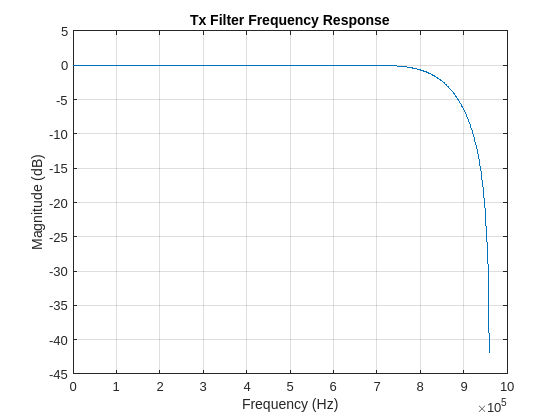

% Initialize transmitter
txObj = helperOFDMTxInit(sysParam);


% Initialize receiver
rxObj = helperOFDMRxInit(sysParam);
    
for simLoopIdx = 1:length(SNRdB)
    % Configure the channel
    chanParam = struct( ...
        'SNR',       SNRdB(simLoopIdx), ...
        'foff',      foff, ...       % normalized frequency offset (ppm)
        'doppler',   fmax*T, ...     % normalized Doppler frequency
        'pathDelay', fadingPathDelays, ...
        'pathGain',  fadingPathGains);
    fprintf('Configuring the fading AWGN channel at %d dB SNR and %d kph...\n', SNRdB(simLoopIdx), v);

    sysParam.txDataBits = []; % clear tx data buffer

    sysParam.timingAdvance = (sysParam.FFTLen + sysParam.CPLen) * ...
        sysParam.numSymPerFrame; % set sample buffer timing advance
    
    % Instantiate an ErrorRate object to cumulatively track BER
    errorRate = comm.ErrorRate();

    fprintf('Transmitting %d frames with transport block size of %d bits per frame...\n', ...
        sysParam.numFrames,sysParam.trBlkSize);
    fprintf('Searching for synchronization symbol...');
    
    % Loop through all frames. Generate one extra frame to obtain the
    % reference symbol for channel estimates of the last frame.
    for frameNum = 1:sysParam.numFrames+1
        sysParam.frameNum = frameNum;

Configuring the fading AWGN channel at 0 dB SNR and 0 kph...


Transmitting 50 frames with transport block size of 346 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 5 dB SNR and 0 kph...


Transmitting 50 frames with transport block size of 346 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 10 dB SNR and 0 kph...


Transmitting 50 frames with transport block size of 346 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 15 dB SNR and 0 kph...


Transmitting 50 frames with transport block size of 346 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 20 dB SNR and 0 kph...


Transmitting 50 frames with transport block size of 346 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 25 dB SNR and 0 kph...


Transmitting 50 frames with transport block size of 346 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 30 dB SNR and 0 kph...


Transmitting 50 frames with transport block size of 346 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 35 dB SNR and 0 kph...


Transmitting 50 frames with transport block size of 346 bits per frame...


Searching for synchronization symbol...

## Payload Generation

I dati utente vengono impacchettati in un **blocco di trasporto**, che viene trasmesso una volta per frame. La dimensione del blocco di trasporto dipende da:

- Il **numero di sottocarrier attivi**,

- Il **numero di sottocarrier pilota** che occupano i sottocarrier attivi,

- L'**ordine di modulazione**,

- Il **tasso di codifica**,

- La **lunghezza del CRC**,

- La **lunghezza del vincolo dell'encoder**,

- Il **numero di simboli dati per frame**.

Per impostazione predefinita, i blocchi di trasporto vengono riempiti con **dati generati casualmente**, ma è possibile trasmettere dati personalizzati. I dati devono essere **divisi in blocchi di trasporto** e, se necessario, l'ultimo blocco deve essere **riempito con zeri** per garantire la lunghezza corretta.

        % Generate random data to transmit. Replace with user data if desired.
        txParam.txDataBits  = randi([0 1],sysParam.trBlkSize,1);

        % Store data bits for BER calculations
        sysParam.txDataBits = [sysParam.txDataBits; txParam.txDataBits];
        sysParam.txDataBits = sysParam.txDataBits(max(1,end-2*sysParam.trBlkSize):end);

## Transmitter Processing

La griglia di trasmissione popola segnali e canali su base **per frame**. La figura sottostante mostra un **frame di trasmissione** composto da **24 simboli OFDM** con una **lunghezza FFT di 256**.

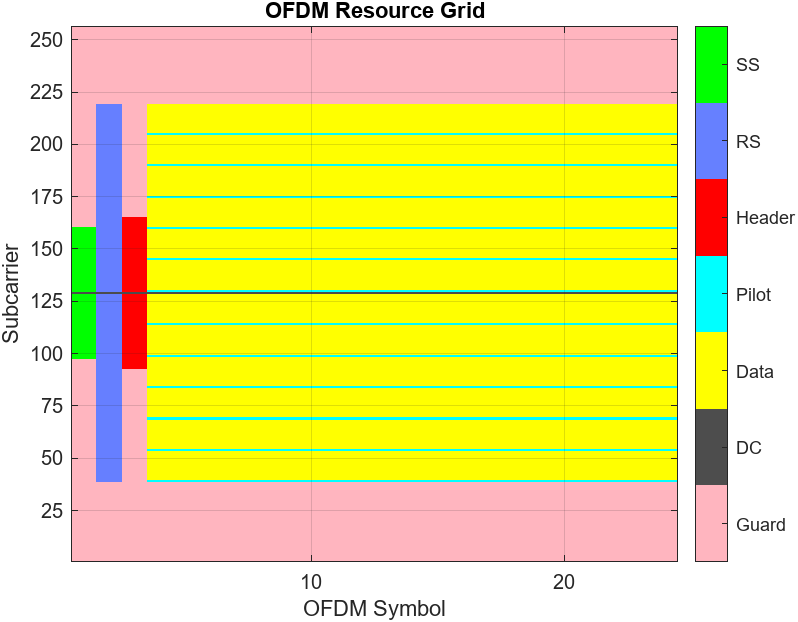

**Simbolo di Sincronizzazione (SS)**

Un segnale di sincronizzazione (**sync signal**) viene trasmesso come **primo simbolo del frame** e consiste in un segnale di **62 sottocarrier** centrato a **DC**. Questo segnale è **indipendente dalla larghezza di banda**, il che significa che tutti i trasmettitori possono inviarlo indipendentemente dalla larghezza di banda assegnata alla cella. Il segnale è progettato per essere rilevato dai ricevitori per **identificare positivamente il segnale della cella** e **determinare il confine del frame** (l'inizio del frame).

**Simbolo di Riferimento (RS)**

Subito dopo il simbolo di sincronizzazione viene trasmesso un **simbolo di riferimento** (**reference symbol**). Questo simbolo fornisce al ricevitore un riferimento noto per **misurare la distorsione del canale** tra trasmettitore e ricevitore. Il ricevitore può quindi compensare tale distorsione per **recuperare il più possibile il segnale originale**.

**Simbolo di Intestazione (Header Symbol)**

Il simbolo di **intestazione** (**header**) trasmette informazioni sulla **larghezza di banda**, lo **schema di modulazione** dei sottocarrier e il **tasso di codifica** dei simboli dati OFDM, permettendo così al ricevitore di **decodificare correttamente il resto del frame**.

Dato che queste informazioni sono fondamentali, l'header viene trasmesso con **margini elevati di segnalazione e codifica** per massimizzare la probabilità di decodifica corretta. Per questo motivo:

- È **codificato con un tasso di 1/2**,

- È **interlacciato ampiamente**,

- È **modulato in BPSK**.

Poiché la distorsione del canale può variare nel tempo, il simbolo di intestazione viene trasmesso **subito dopo il simbolo di riferimento**, per **massimizzare la probabilità di ricezione corretta**. Inoltre, dato che la larghezza di banda non è ancora nota, l'header viene **sempre trasmesso su 72 sottocarrier centrati a DC**.**Segnali Pilota (Pilot Signals)**

Per contrastare il **jitter di fase** che si verifica alle alte frequenze di trasmissione, i **piloti** vengono trasmessi a **intervalli fissi di sottocarrier** all'interno dei simboli dati. Questo permette al ricevitore di **avere un riferimento di fase**.

**Sottocarrier DC e di Guardia (DC and Guard Subcarriers)**

- **I sottocarrier nulli ai bordi dello spettro di trasmissione** servono per **limitare l'energia spettrale** entro una larghezza di banda specificata.

- **Il sottocarrier a DC viene annullato** per mantenere l'energia del segnale entro il **range lineare dell'amplificatore di potenza**.

**Architettura del Trasmettitore**

Il trasmettitore genera sia **segnali di controllo** (sincronizzazione, riferimento, intestazione e piloti) sia **segnali dati** (blocco di trasporto). I simboli di **sincronizzazione, riferimento e intestazione** vengono generati separatamente e **multiplexati nel tempo** con i simboli dati.

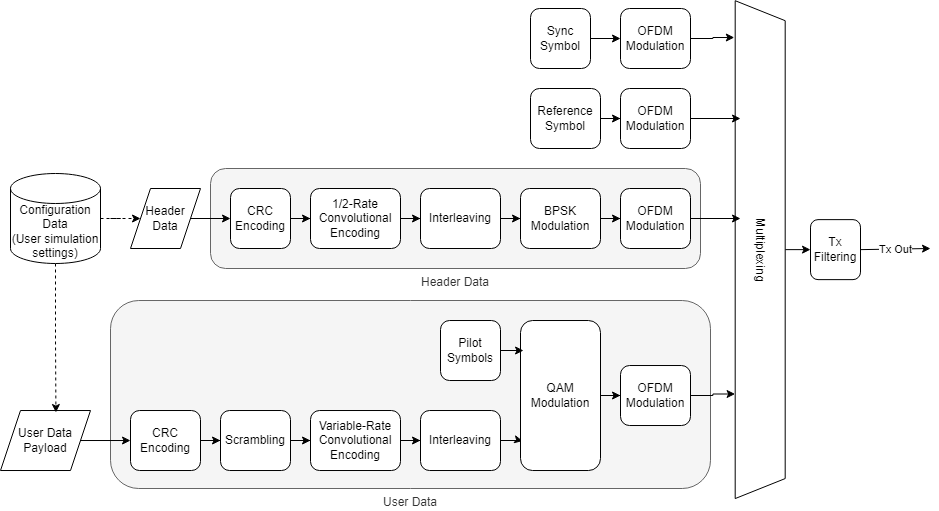

I **simboli dati** sono costituiti da un **singolo utente** che trasmette un **singolo blocco di trasporto** per frame.

- Un oggetto `comm.CRCGenerator` calcola il **CRC** per il **payload del blocco di trasporto** e lo aggiunge al payload.

- I dati vengono **scramble-ati** in modo additivo utilizzando un oggetto `comm.PNSequence` per **distribuire uniformemente la potenza del segnale** nello spettro di trasmissione.

- L'**interleaving** viene eseguito con la funzione `reshape` per resistere agli **errori a raffica** causati da profondi fading.

- La **codifica convoluzionale** introduce **bit ridondanti per la correzione degli errori** in avanti e viene eseguita con la funzione `convenc`.

- Il **puncturing** riduce il numero di bit ridondanti per **aumentare la velocità di trasmissione dei dati**.

- Il **blocco di trasporto viene modulato** utilizzando la funzione `qammod` e preparato per la trasmissione in un frame OFDM.

- Tutti i segnali vengono **modulati OFDM** utilizzando la funzione `ofdmmod`.

- Il segnale viene **filtrato per ridurre le emissioni fuori banda** utilizzando `dsp.FIRFilter`, con coefficienti generati tramite le funzioni di progettazione di filtri `firpmord` e `firpm`.

        % Transmit data
        [txOut,txGrid,txDiagnostics] = helperOFDMTx(txParam,sysParam,txObj);

## Apply Channel and Hardware Impairments

Introduci disturbi per corrompere il segnale trasmesso, inclusi **fading**, **rumore bianco gaussiano additivo (AWGN)** e **offset di frequenza della portante**. L'**impulse response** del canale può essere opzionalmente visualizzato per osservare il potenziale **inter-symbol interference (ISI)** che si propaga al di fuori della regione del **prefisso ciclico** del simbolo OFDM.

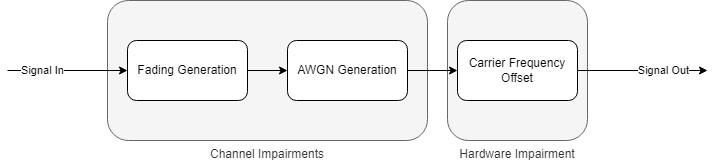

**Fading**

Un oggetto `comm.RayleighChannel` viene utilizzato per applicare il **Rayleigh fading** al segnale trasmesso. L'uso di un oggetto consente di mantenere **le statistiche del canale internamente** tra le chiamate all'oggetto. Poiché la **frequenza Doppler** è una funzione della frequenza di trasmissione, viene utilizzato il **parametro Doppler normalizzato** per rappresentare la frequenza Doppler e mostrare più facilmente l'impatto della velocità mobile indipendentemente dalla frequenza della portante.

**Rumore Additivo**

La funzione `awgn` viene utilizzata per applicare **AWGN** al segnale attenuato dal fading. La **potenza di ingresso** nella funzione `awgn` è calcolata come una funzione della potenza della costellazione per sottocarrier e del numero di sottocarrier occupati. Questa potenza di ingresso viene passata alla funzione `awgn`, insieme con il **SNR target**, per ottenere il **SNR desiderato**.

**Offset di Frequenza della Portante**

Infine, l'**offset di frequenza** viene applicato all'interno del blocco del canale. Si utilizza la funzione `comm.PhaseFrequencyOffset` per **ruotare il segnale nel dominio del tempo** della frequenza desiderata.

        % Process one frame of samples through channel
        chanOut = helperOFDMChannel(txOut,chanParam,sysParam, BWstruct);

## Channel Visualization

Utilizza la funzione `spectrumAnalyzer` per visualizzare lo **spettro ricevuto** dopo che il fading e il rumore sono stati aggiunti al segnale trasmesso. Durante l'esecuzione della simulazione, potrai osservare come la **costellazione del segnale ricevuto** venga negativamente influenzata dai **nulli spettrali** causati dal **fading multi-percorso**.

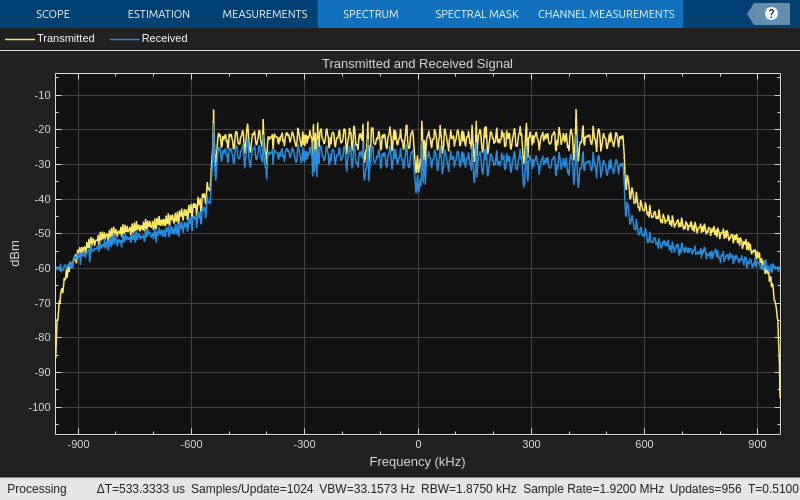

        if userParam.enableScopes    
            sa(txOut,chanOut);
        end

## Receiver Processing

Il **ricevitore** inverte il processo di elaborazione del **trasmettitore**. Deve anche rilevare e correggere le distorsioni causate da **sincronizzazione asincrona**, **offset di frequenza**, **rumore**, **fading variabile nel tempo**, **fading selettivo in frequenza** e **jitter di fase**.

Il segnale viene **filtrato passa-basso** per rimuovere l'energia fuori banda che potrebbe introdurre rumore. All'inizio della simulazione del ricevitore, viene eseguita la **rilevazione del segnale di sincronizzazione** tramite **correlazione nel dominio del tempo** e **soglia** per determinare l'inizio del frame. Fino a quando il simbolo di sincronizzazione non viene rilevato, il ricevitore non è "associato" (campato) a nessuna stazione base.

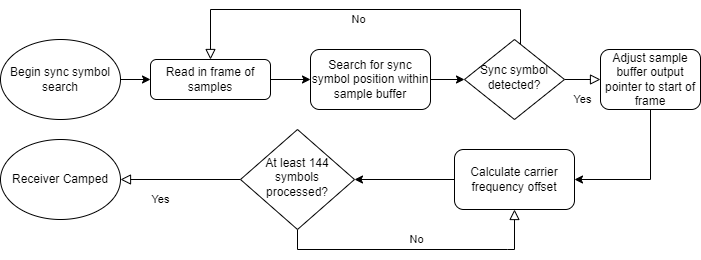

Dopo il rilevamento della sincronizzazione con successo, vengono utilizzati **144 simboli** per la **correzione automatica della frequenza (AFC)**, al fine di stimare l'**offset di frequenza** rilevando lo **spostamento di fase** tra il **prefisso ciclico** (una copia della fine dei campioni del simbolo che viene trasmessa all'inizio di un simbolo OFDM) e la fine del simbolo. Vengono utilizzati **sei simboli** per ottenere una stima dell'offset di frequenza, e le ultime **24 stime** vengono mediate per ottenere la stima finale filtrata del **CFO (Carrier Frequency Offset)**.

Combinando questa informazione con la conoscenza della **durata di un simbolo OFDM**, l'offset di frequenza può essere stimato utilizzando il calcolo del **prodotto interno**. Successivamente, l'offset di frequenza viene corretto con un **oscillatore controllato numericamente** utilizzando l'oggetto `comm.PhaseFrequencyOffset`.

Una volta che il segnale è stabile rispetto all'**offset temporale** e all'**offset di frequenza**, il ricevitore viene considerato **campato** e **connesso**, e l'intero frame viene **demodulato** nei **sottocarrier OFDM** utilizzando la funzione `ofdmdemod`.

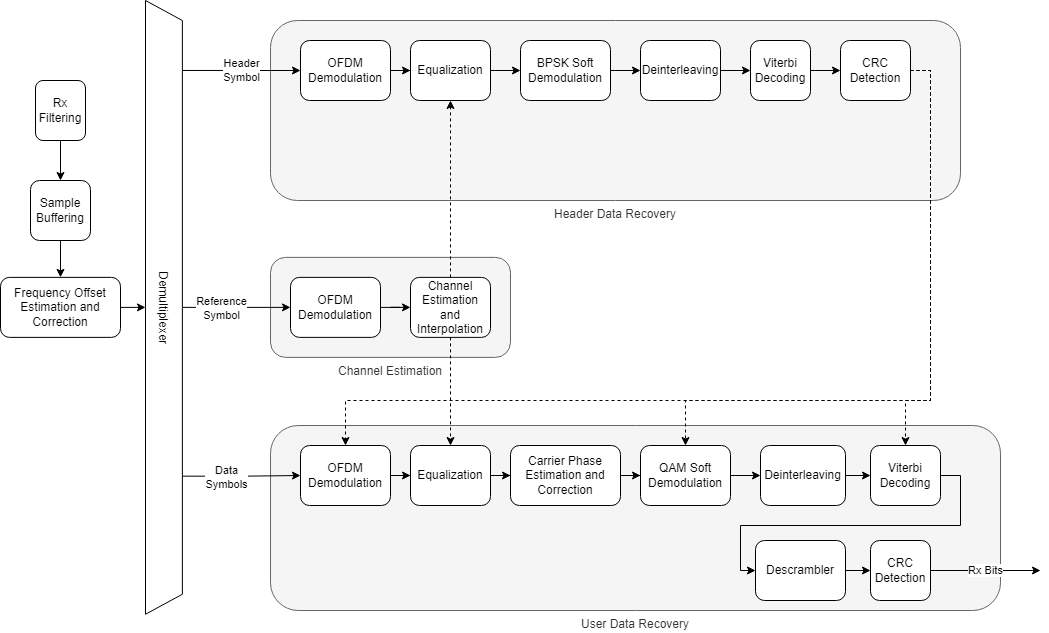

Per combattere il **fading variabile nel tempo**, vengono utilizzati **due simboli di riferimento** da **frame adiacenti** per stimare il canale in momenti diversi. Successivamente, le stime del canale tra i due simboli di riferimento vengono **interpolate linearmente** per fornire le stime del canale per i simboli di **header** e **dati**. I simboli vengono quindi **equalizzati** utilizzando le stime del canale con la funzione `ofdmEqualize`.

L'**header** viene estratto e decodificato per ottenere i parametri dei simboli dati, come la **lunghezza FFT**, il **tipo di modulazione dei sottocarrier** e il **tasso di codifica**. I simboli dati vengono quindi **demodulati** in base ai parametri dell'header.

I **piloti** all'interno dei simboli dati vengono utilizzati per stimare l'**errore di fase comune (CPE)**, tipicamente causato da **jitter di fase** nelle trasmissioni **mmWave**. Il CPE influisce ugualmente su tutti i sottocarrier. L'errore viene **rimosso** (derotato) per eliminare il CPE dai simboli dati, e i sottocarrier dati vengono **decodificati soft** in **log-likelihood ratios (LLR)** utilizzando la funzione `qamdemod`.

Una volta che il **bitstream** è disponibile, i **bit** vengono **deinterlacciati** prima che venga eseguita la **decodifica a massima verosimiglianza** utilizzando la funzione `vitdec`, che implementa l'**algoritmo di Viterbi**. I bit vengono poi **descramblati**, e l'oggetto `comm.CRCDetector` calcola il **CRC** e lo confronta con il **CRC** aggiunto nel payload per la **verifica del trasport block**.

...................................................


Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
.......................................


Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
.......................................


Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
.......................................


Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
.......................................


Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
.......................................


Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
.......................................


Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
.......................................

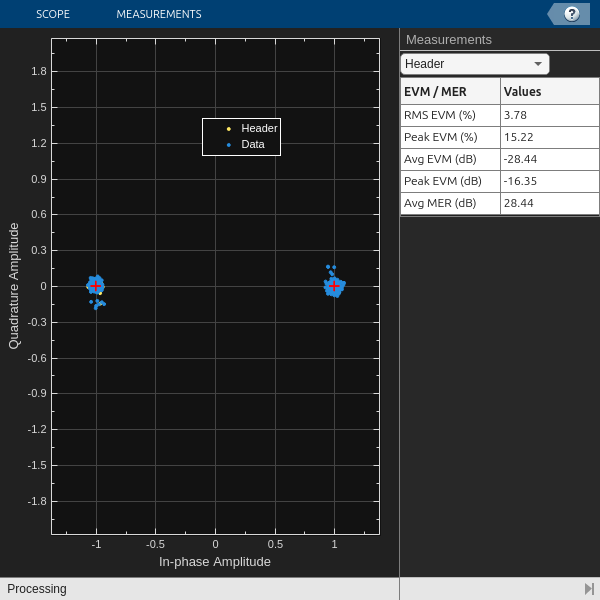

        % Run the receiver front-end
        rxIn = helperOFDMRxFrontEnd(chanOut,sysParam,rxObj);

        % Run the receiver processing
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj);
        sysParam.timingAdvance = toff;

        % Collect bit and frame error statistics
        if isConnected    
            % Continuously update the bit error rate using the |comm.ErrorRate|
            % system object
            BER = errorRate(...
                sysParam.txDataBits(end-(2*sysParam.trBlkSize)+(1:sysParam.trBlkSize)), ...
                rxDataBits);
        end

## Receiver Performance Visualization

Utilizza l'oggetto `comm.ConstellationDiagram` per visualizzare sia la **costellazione dell'header** che la **costellazione dei dati** in un unico grafico. Variare gli **impedimenti del canale** ti consente di visualizzare il **rumore** dopo la compensazione degli **impedimenti del ricevitore** per tutti i sottocarrier sovrapposti nel grafico. **EVM** (Error Vector Magnitude) e **MER** (Modulation Error Ratio) possono essere misurati rispetto alla **costellazione di riferimento** per ogni tipo di **modulazione dei dati**.

Questa visualizzazione ti permette di monitorare l'effetto delle **distorsioni del canale** sulle costellazioni, permettendo di osservare visivamente il livello di rumore e la qualità del segnale dopo il processo di compensazione degli impedimenti del ricevitore.

        if isConnected && userParam.enableScopes
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                      complex(rxDiagnostics.rxConstellationData(:)));
        end
    end % frame loop

Simulation completed at 0 SNR: Base station not detected.


Simulation completed at 5 SNR: BER = 8.863198e-02, FER = 7.435897e-01


Simulation completed at 10 SNR: BER = 1.259819e-02, FER = 5.128205e-02


Simulation completed at 15 SNR: BER = 0, FER = 0


Simulation completed at 20 SNR: BER = 0, FER = 0


Simulation completed at 25 SNR: BER = 0, FER = 0


Simulation completed at 30 SNR: BER = 0, FER = 0


Simulation completed at 35 SNR: BER = 0, FER = 0


## Clear Simulation and Compute Statistics

Dopo il **trattamento del frame**, è importante **ripulire** le informazioni di stato memorizzate nelle **variabili persistenti** utilizzando il comando `clear`. Le statistiche accumulate del **bit error rate (BER)** e del **frame error rate (FER)** vengono calcolate e visualizzate per il **SNR simulato**. Successivamente, la simulazione carica il **successivo valore di SNR** e avvia una nuova esecuzione.

Questo processo consente di eseguire la simulazione su diverse condizioni di SNR e di raccogliere i risultati relativi all'affidabilità della trasmissione, come **BER** e **FER**, per vari valori di **SNR** durante il ciclo di simulazione.

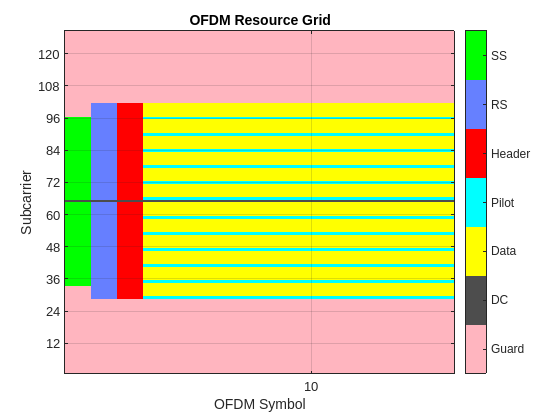

    % Clear out the |persistent| variables for the sync detection flag and
    % camped flag
    clear helperOFDMRx;

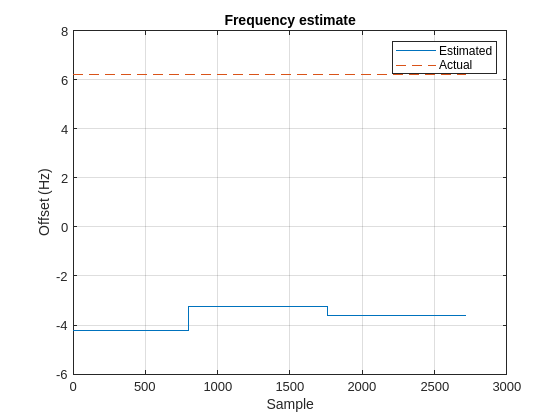

    clear helperOFDMRxSearch;

    % Compute data diagnostics
    if isConnected
        FER = sum(rxDiagnostics.dataCRCErrorFlag) / length(rxDiagnostics.dataCRCErrorFlag);
        fprintf('Simulation completed at %d SNR: BER = %d, FER = %d\n',SNRdB(simLoopIdx),BER(1),FER);
        BERResults(simLoopIdx) = BER(1);
    else
        fprintf('Simulation completed at %d SNR: Base station not detected.\n',SNRdB(simLoopIdx));
        fprintf('\n');
        BERResults(simLoopIdx) = 0.5; % default to high BER for plotting purposes

    end

    % Release object to reconfigure for the next simulation run
    release(errorRate);
    
% SNR loop end
end

## Diagnostics

Una **struttura diagnostica** cattura vari **parametri** per l'analisi durante la simulazione. Le **prestazioni del ricevitore** possono essere registrate e tracciate, come ad esempio il **monitoraggio dell'offset di frequenza** dell'ultimo frame e il **monitoraggio della stima del canale**. Inoltre, è possibile calcolare e visualizzare **metriche di errore** come **BER (Bit Error Rate)** e **FER/BLER (Frame Error Rate / Block Error Rate)**.

Questo ti permette di analizzare in modo dettagliato le **prestazioni** del sistema di comunicazione durante la simulazione, osservando come l'errore di trasmissione e la qualità del segnale cambiano con l'aumento dell'**offset di frequenza** o della **distorsione del canale**, nonché monitorando i **tassi di errore** in tempo reale.

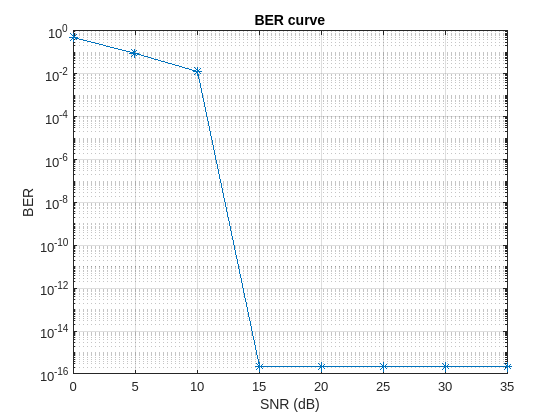

% Plot the transmission grid
helperOFDMPlotResourceGrid(txGrid,sysParam);


% Plot the frequency offset estimator output
figure;
plot(rxDiagnostics.estCFO*sysParam.scs);
hold on;
plot(foff*fsamp*ones(length(rxDiagnostics.estCFO),1)/1e6,'--');
title('Frequency estimate');
xlabel('Sample');
ylabel('Offset (Hz)');
grid on;
legend('Estimated','Actual');

% Plot a BER curve if more than one SNR was specified
if length(SNRdB) > 1
    figure;
    semilogy(SNRdB,BERResults+eps,'-*'); % add eps if no errors found
    title('BER curve');
    xlabel('SNR (dB)');
    ylabel('BER');
    grid on;
end